co=load("Het_co_beta70.mat");
nonco=load("Het_nonco_beta70.mat");

t=0:1:length(nonco.het)-1; %in mins

alpha=3*10^-6;
tau=15;
Iss=559.5;
B0=1000;
Y=100;
d=0.1;
Bss=367;

T=tau+1/(d+alpha*Iss);

R0 = 0.2072

ans = 4.9134

T = 23.7087

R0_int = 0.2332

ans = 5.7927

T_int = 24.8349

ans = 1.0475

T = 24.8349

t=t/T;

h_n=find(nonco.het<0.3);
h_n_f=find(h_n>5000,1);
ti_n=h_n(h_n_f)

ti_n = 10708


z_n=find(nonco.nonzero_frac<0.01);
z_n_f=find(z_n>10000,1);
tf_n=z_n(z_n_f)

tf_n = 98006

if isempty(tf_n)
   tf_n=120000 
end 

z_c=find(co.nonzero_frac<0.01);
z_c_f=find(z_c>10000,1);
tf_c=z_c(z_c_f)

tf_c = 104999

if isempty(tf_c)
   tf_c=120000 
end 

h_c=find(co.het<0.3);
h_c_f=find(h_c>5000,1);
ti_c=h_c(h_c_f)

ti_c = 11691

fit_nonco=polyfit(t(ti_n:tf_n)', log(nonco.het(ti_n:tf_n)), 1);
y_nonco=exp(fit_nonco(2)+fit_nonco(1)*t(ti_n:tf_n));
Ne_nonco=-2/fit_nonco(1)

Ne_nonco = 1.5996e+03


ft = fittype('poly1');
[obj,gof,opt] = fit(t(ti_n:tf_n)',log(nonco.het(ti_n:tf_n)),ft);
coefficients = coeffvalues(obj);
gradient = coefficients(1);
intercept = coefficients(2);
level = 2*tcdf(-1,gof.dfe);
int = confint(obj,1-level);
gradient;
gradient_error = abs((int(1,1)-int(2,1))/2);
intercept;
intercept_error = abs((int(1,2)-int(2,2))/2);
Ne_nonco_fit=-2/gradient

Ne_nonco_fit = 1.5996e+03

Ne_nonco_error=abs(Ne_nonco_fit*gradient_error/gradient)

Ne_nonco_error = 0.1799


fit_co=polyfit(t(ti_c:tf_c)', log(co.het(ti_c:tf_c)), 1);
y_co=exp(fit_co(2)+fit_co(1)*t(ti_c:tf_c));
Ne_co=-2/fit_co(1)

Ne_co = 1.6957e+03


ft = fittype('poly1');
[obj,gof,opt] = fit(t(ti_c:tf_c)',log(co.het(ti_c:tf_c)),ft);
coefficients = coeffvalues(obj);
gradient = coefficients(1);
intercept = coefficients(2);
level = 2*tcdf(-1,gof.dfe);
int = confint(obj,1-level);
gradient;
gradient_error = abs((int(1,1)-int(2,1))/2);
intercept;
intercept_error = abs((int(1,2)-int(2,2))/2);
Ne_co_fit=-2/gradient

Ne_co_fit = 1.6957e+03

Ne_co_error=abs(Ne_co_fit*gradient_error/gradient)

Ne_co_error = 0.1230

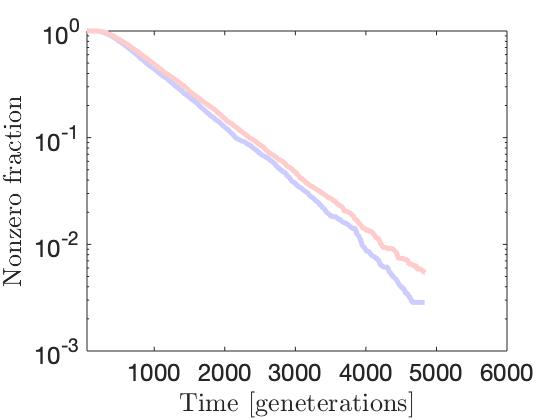

plot(t, nonco.nonzero_frac, 'Color', [0.8 0.8 1] ,'LineWidth', 5)
hold on
plot(t, co.nonzero_frac, 'Color', [1 0.8 0.8] ,'LineWidth', 5)
hold off
set(gca,'YScale','log')
xlabel('Time [geneterations]', 'Interpreter',"latex")
ylabel('Nonzero fraction', 'Interpreter',"latex")
set(gca, 'FontSize', 24)
% ylim([10^-2 1])
xlim([47 6000])

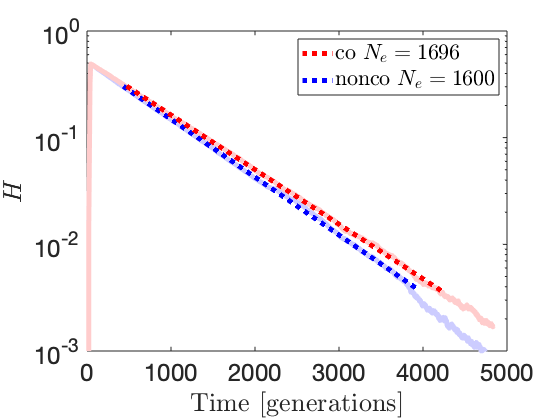

plot(t, nonco.het, 'Color', [0.8 0.8 1] ,'LineWidth', 5)
hold on
plot(t, co.het, 'Color', [1 0.8 0.8] ,'LineWidth', 5)
n=plot(t(ti_n:tf_n), y_nonco, 'b:', 'LineWidth', 5);
c=plot(t(ti_c:tf_c), y_co, 'r:', 'LineWidth', 5);
hold off
set(gca,'YScale','log')
% title('co Ne=356')
% xlim([0 2.5e4])
% xlabel('Time [min]')
xlabel('Time [generations]', 'Interpreter',"latex")
ylabel('$H$', 'Interpreter',"latex")
% legend([c, n], 'co $N_{e}=1696$', 'nonco $N_{e}=1600$','interpreter','latex', 'location', "northeast")
% legend('nonco', 'co','interpreter','latex', 'location', "northeast")
set(gca, 'FontSize', 24)
% ylim([10^-2 1])
% xlim([47 5500])
ylim([0.001 1])